# PDE weak form parameter estimation: KS equation

Kuramoto-Sivashinsky equation: $\partial_t \;u+u\partial_x \;u+\partial_x^2 \;u+\partial_x^4 \;u=0$

KS equation describes: 

- chaotic dynamics of laminar flame fronts: G. Sivashinsky, Nonlinear analysis of hydrodynamic instability in laminar flames: I. derivation of basic equations, Acta Astronaut. 4, 1177 (1977).

- reaction-diffusion systems: Y. Kuramoto and T. Tsuzuki, Persistent propagation of concentration waves in dissipative media far from thermal equilibrium, Prog. Theor. Phys. 55, 356 (1976).

- coating flows: G. I. Sivashinsky and D. Michelson, On irregular wavy flow of a liquid film down a vertical plane, Prog. Theor. Phys. 63, 2112 (1980).

Data and code (modified) from Rudy et al (2017) and Reinbold et al (2020).

- Paper Rudy: [https://www.science.org/doi/10.1126/sciadv.1602614](https://www.science.org/doi/10.1126/sciadv.1602614) 

- Github Rudy: [https://github.com/snagcliffs/PDE-FIND](https://github.com/snagcliffs/PDE-FIND) 

- Paper Reinbold: [https://journals.aps.org/pre/pdf/10.1103/PhysRevE.101.010203](https://journals.aps.org/pre/pdf/10.1103/PhysRevE.101.010203) 

- Github Reinbold: [https://github.com/pakreinbold/PDE_Discovery_Weak_Formulation](https://github.com/pakreinbold/PDE_Discovery_Weak_Formulation)   

## Kuramoto-Sivashinsky data

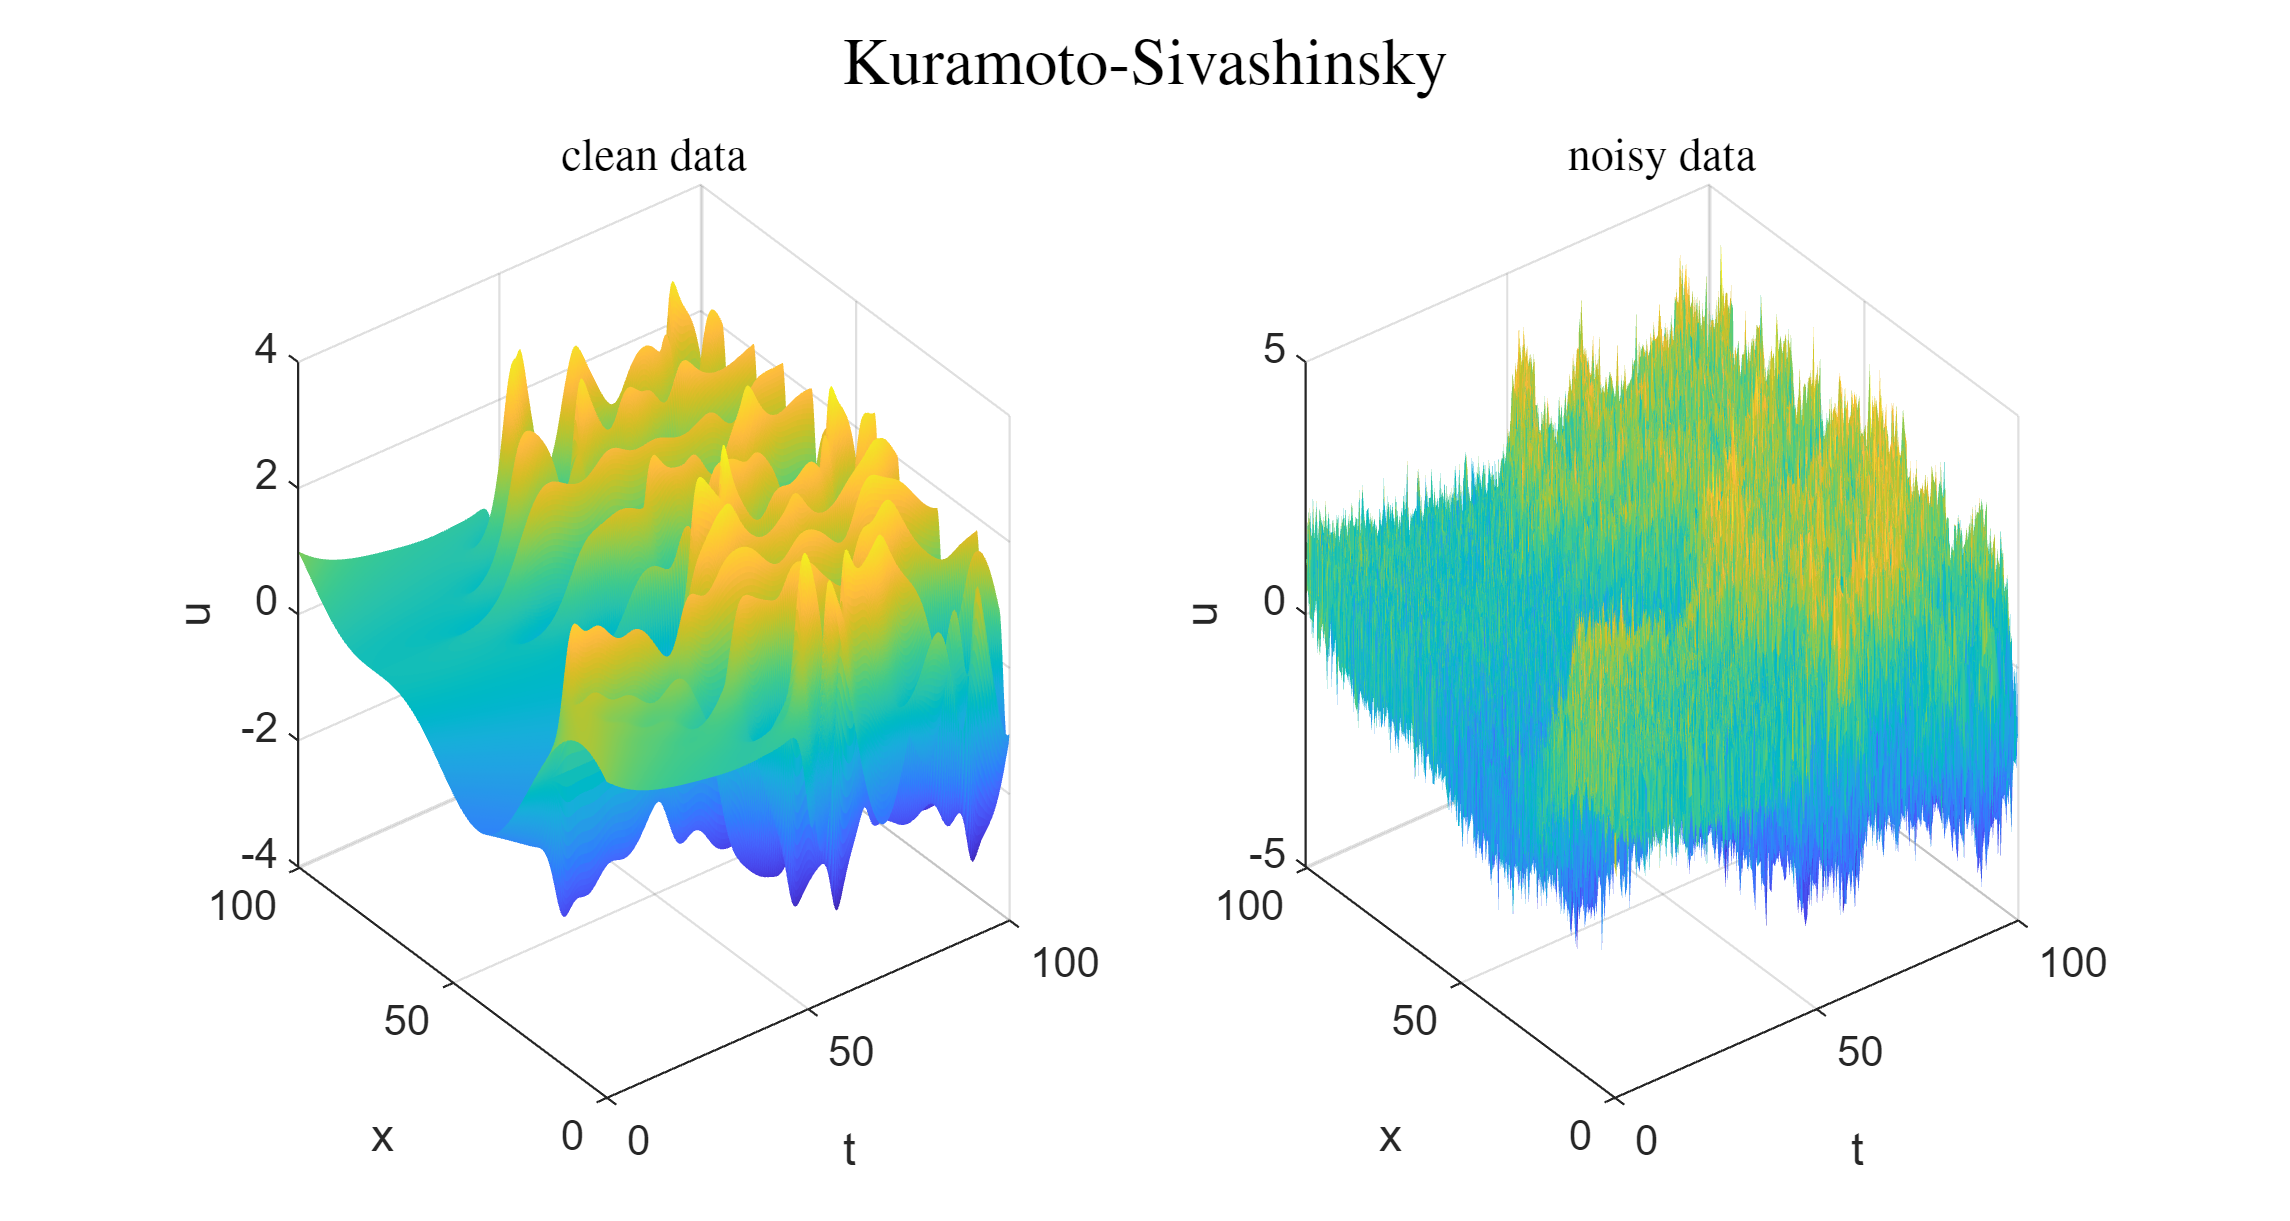

addpath(genpath(pwd))

% load data
traj = matfile('KS_data'); 

% grid densities
dt = traj.dt;
dx = traj.dx; 

% size of velocity fields
[Lx,Lt] = size(traj,'uu');

% add noise
sig = 0.0;
sig = 0.01;
sig = 0.5;

Ua = traj.uu; 
Ua = Ua + sig*std(Ua(:))*randn(size(Ua)); % Gaussian

% plot data
plotPDEdata(traj,Ua,'Kuramoto-Sivashinsky')

## PDE parameter estimation with standard least squares

% compute derivatives using finite difference
ut=[];
for xpos=1:size(Ua,1)
    ut(xpos,:)=FiniteDiff(real(Ua(xpos,:)),dt,1);
end

ux=[];uxx=[];uxxxx=[];
for kk=1:size(Ua,2)
    ux(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,1);
    uxx(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,2);
    uxxxx(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,4);
end


% time derivatives: left hand side
LHS = -ut(:);

% library: right hand side
uux = Ua.*ux; 
RHS = [uux(:), uxx(:), uxxxx(:)]; % advection term, Laplacian, biharmonic


KS_params = RHS\LHS; % Least squares to estimate the coefficients of the PDE

% print coefficients
ThetaLIST = {'uu_{x}','u_{xx}','u_{xxxx}'}';
KS_params_print = [ThetaLIST, num2cell(KS_params)]

KS_params_print = 3×2 cell array
    {'uu_{x}'  }    {[     0.0028]}
    {'u_{xx}'  }    {[-6.9280e-06]}
    {'u_{xxxx}'}    {[-1.0079e-07]}



% error
c = ones(3,1); % KS true model coefficients
error = abs(KS_params(1:3)-c)./c % model coefficient error

error =     0.9972
    1.0000
    1.0000


# PDE parameter estimation using weak formulation

## Test function

% Discretization test function integration domain
Dx = 100;
Dt = 50;

% Create test function integration subdomain
x = linspace(-1,1,Dx+1); 
t = linspace(-1,1,Dt+1);

% integration domain size: domain from -1:1 -> dx*Dx = 2*Hx
Hx = dx*Dx/2; 
Ht = dt*Dt/2;

% number of integration domains
N_d = 100;

% Time and space sampling scheme: random integration domains
P = zeros(2,N_d);
P(1,:) = randi([1,Lx-Dx],N_d,1);
P(2,:) = randi([1,Lt-Dt],N_d,1);

% Initialize Target and Library
q0 = zeros(N_d,1);
Q = zeros(length(q0),3);
     

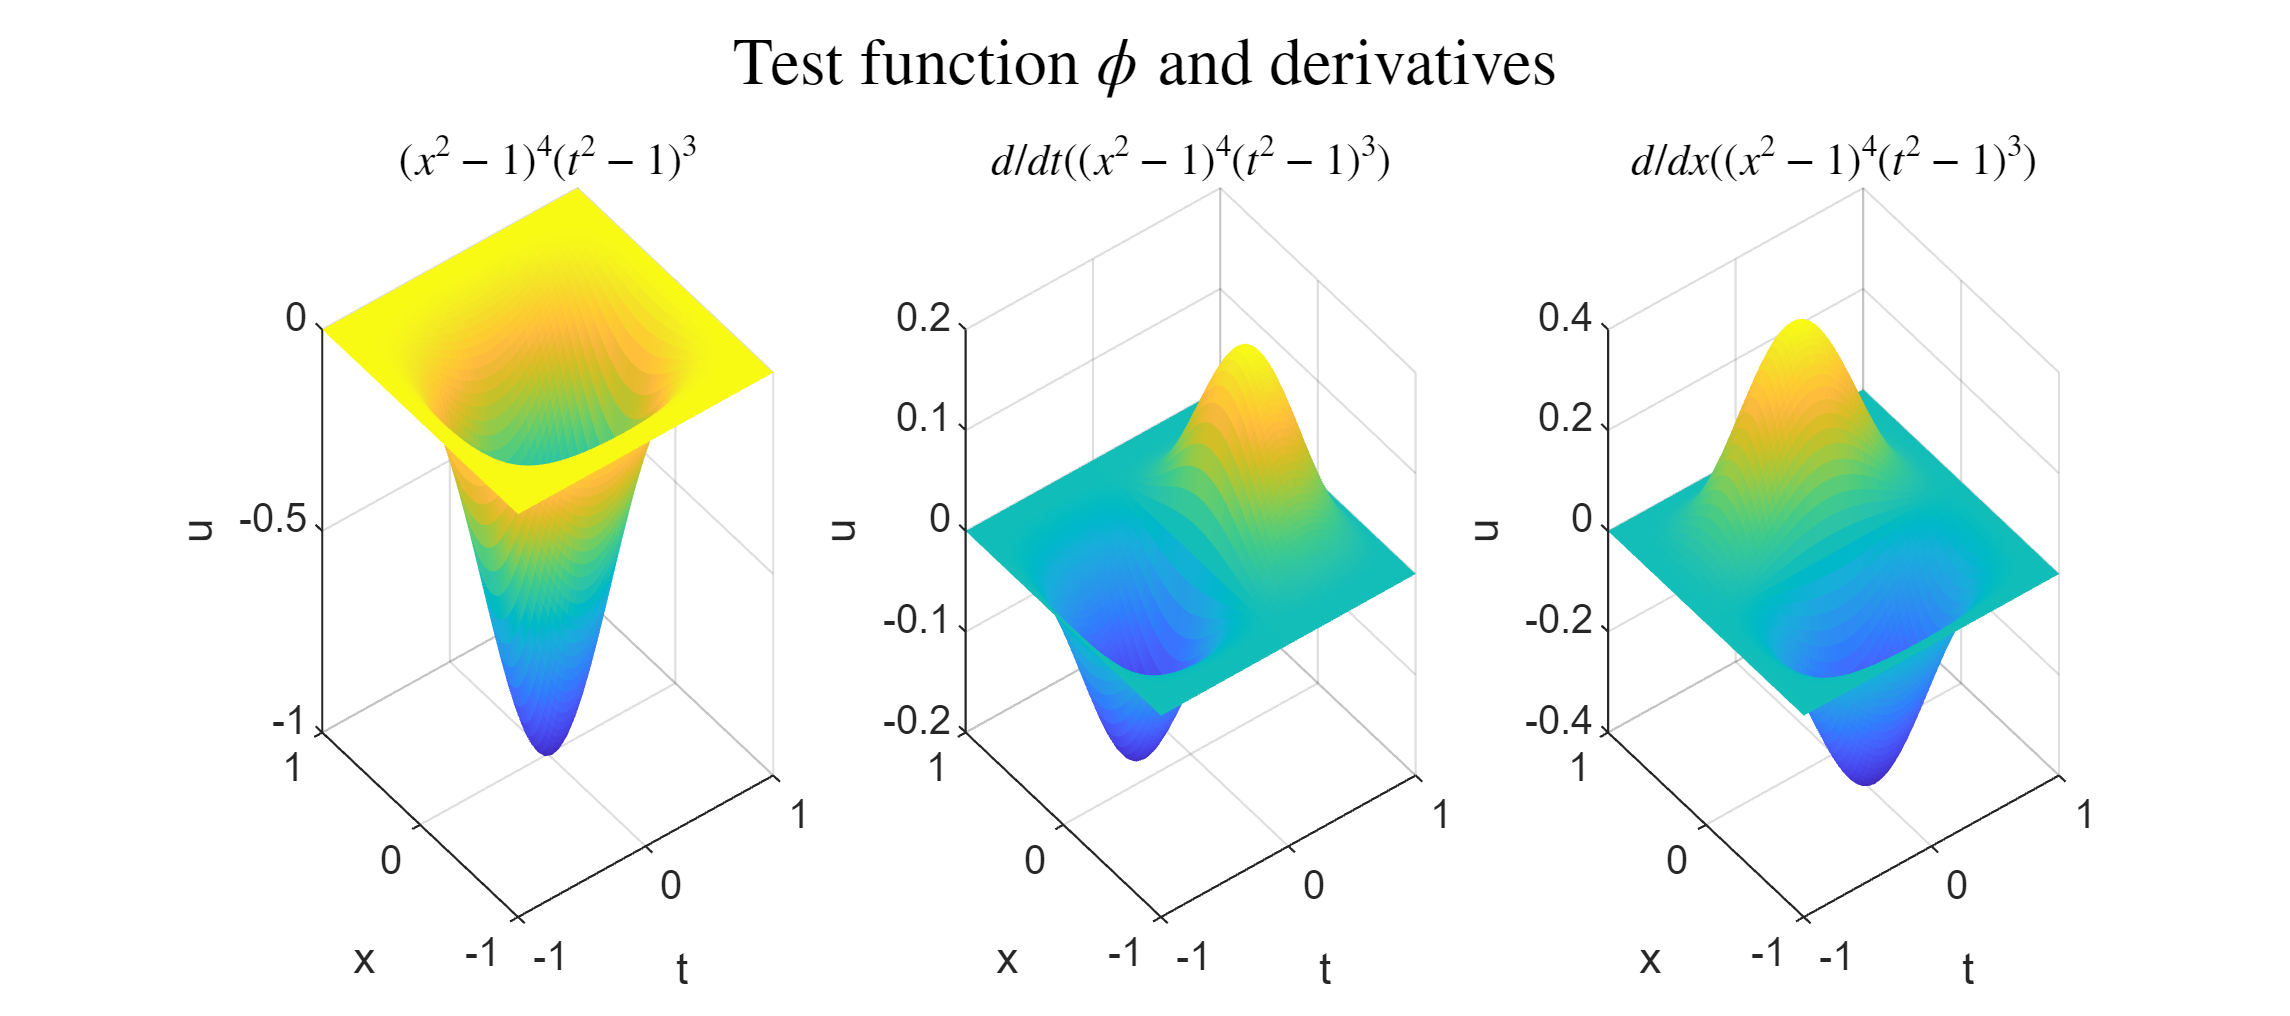

% Test functions phi = (x^2 - 1)^p_k * (t^2 - 1)^p_t
% derivatives: d/dx^k_x d/dt^k_t ( (x^2 - 1)^4 * (t^2 - 1)^3 )
% testFun([k_x,k_t],[p_x, p_t],x,t,Hx,Ht)
p = [4,3]; % test function exponents: 
phi00 = testFun([0,0],p,x,t,Hx,Ht); % (x^2 - 1)^4 * (t^2 - 1)^3
phi01 = testFun([0,1],p,x,t,Hx,Ht); % d/dt ( (x^2 - 1)^4 * (t^2 - 1)^3 )
phi10 = testFun([1,0],p,x,t,Hx,Ht); % d/dx ( (x^2 - 1)^4 * (t^2 - 1)^3 )
phi20 = testFun([2,0],p,x,t,Hx,Ht); % d/dx^2 ( (x^2 - 1)^4 * (t^2 - 1)^3 )
phi30 = testFun([3,0],p,x,t,Hx,Ht); % d/dx^3 ( (x^2 - 1)^4 * (t^2 - 1)^3 )
phi40 = testFun([4,0],p,x,t,Hx,Ht); % d/dx^4 ( (x^2 - 1)^4 * (t^2 - 1)^3 )

% plot test function
plotTF(x,t,phi00,phi01,phi10)

## Compute weak form target and library

% generate N_d weak form LHS (target) and RHS (library)
for np = 1:N_d  
    % Indices for integration domain
    rx = P(1,np):(P(1,np)+Dx);
    rt = P(2,np):(P(2,np)+Dt);

    % Velocity fields on integration domain
    U = Ua(rx,rt); 

    % Target: du/dt
    B = U.*phi01; 
    q0(np,1) = trapz(x,trapz(t,B,2),1); % numerical integration via the trapezoidal method
    
    % Advection Term 
    th1 = -(1/2)*U.^2.*phi10; 
    Q(np,1) = trapz(x,trapz(t,th1,2),1);
    % Laplacian Term
    th2 = U.*phi20;
    Q(np,2) = trapz(x,trapz(t,th2,2),1);
    % Biharmonic Term
    th3 = U.*phi40; 
    Q(np,3) = trapz(x,trapz(t,th3,2),1);
end
            

## Identify PDE with weak form SINDy

KS_params = Q\q0; % Least squares to estimate the coefficients of the PDE

% print coefficients
ThetaLIST = {'uu_{x}','u_{xx}','u_{xxxx}'}';
KS_params_print = [ThetaLIST, num2cell(KS_params)]

KS_params_print = 3×2 cell array
    {'uu_{x}'  }    {[0.9787]}
    {'u_{xx}'  }    {[0.9621]}
    {'u_{xxxx}'}    {[0.9545]}



% error
c = ones(3,1); % KS model terms
error_weakForm = abs(KS_params(1:3)-c)./c % model coefficient error

error_weakForm =     0.0213
    0.0379
    0.0455
